data_dir = '/home/przemek/neurodata/ca_mecp2_culture/signal';
filepaths = listfiles(data_dir, '.*mat');

all_F_stats = [];
unfiltered_F_stats = [];
for i=1:numel(filepaths)
    filepath = filepaths{i};
    dat = load(filepath);
    Fcell = dat.dat.Fcell{1};
    FcellNeu = dat.dat.FcellNeu{1};
    fstat = FStats(dat.dat);
    all_F_stats = [all_F_stats filterFstat(fstat)];
    unfiltered_F_stats = [unfiltered_F_stats fstat];
end
nstats = numel(all_F_stats);

Set up conditions variable

all_conditions = arrayfun(@(x) x.condition, [all_F_stats.fileinfo], 'uniformoutput', false);
[all_condition_group, unique_conditions] = findgroups(lower(all_conditions));
colours_array = hsv(numel(unique_conditions));
condition_index = containers.Map(unique_conditions, 1:numel(unique_conditions));
condtion_colours = containers.Map(unique_conditions, num2cell(colours_array,2));


Count of ROI in recordings

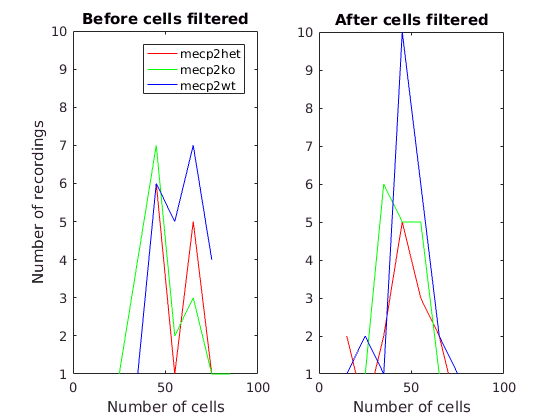

ncells = [all_F_stats.ncells];
unfiltered_ncells = [unfiltered_F_stats.ncells];

for i=1:numel(unique_conditions)
    fi = find(all_condition_group == i);
    colors = condtion_colours.values;
    bin_width = 10;

    subplot(1,2,1);
    [N,edges] = histcounts(unfiltered_ncells(fi),'BinWidth', bin_width);
    bin_centres = edges(1:end-1) + bin_width / 2;
    plot(bin_centres, N, 'Color', colors{i});    
    hold on;    
    subplot(1,2,2);
    [N,edges] = histcounts(ncells(fi),'BinWidth', bin_width);
    bin_centres = edges(1:end-1) + bin_width / 2;
    plot(bin_centres, N, 'Color', colors{i});
    
    hold on;
end
hold off;

subplot(1,2,1)
legend(unique_conditions);
title('Before cells filtered')
ylabel('Number of recordings')
xlabel('Number of cells')
ylim([1 10]);

subplot(1,2,2)
title('After cells filtered')
xlabel('Number of cells')
ylim([1 10]);


ncells_mean = splitapply(@mean,[all_F_stats.ncells],all_condition_group);
ncells_std = splitapply(@std,[all_F_stats.ncells],all_condition_group);
unique_conditions

unique_conditions =     'mecp2het'    'mecp2ko'    'mecp2wt'


ncells_mean

ncells_mean =    45.6667   45.6842   46.7826


ncells_std

ncells_std =    18.0700   14.7424   12.4534



keep_stats = ncells>=30;
F_stats = all_F_stats(keep_stats);
nstats = numel(F_stats);
conditions = all_conditions(keep_stats);
condition_group = all_condition_group(keep_stats);

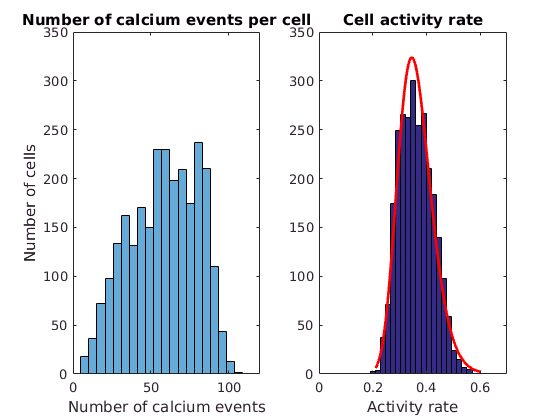

events_count = [];
activity_rates = [];
df_max = [];
for i=1:numel(all_F_stats)
    events_count = [events_count ...
        cellfun(@(x) numel(x), all_F_stats(i).peaks')];
    activity_rates = [activity_rates ...
        sum(all_F_stats(i).peak_extends, 2)' / size(all_F_stats(i).dF, 2)];
    df_max = [df_max max(all_F_stats(i).dF, [], 2)'];
end
ax1 = subplot(1,2,1);
histogram(events_count, 20);
xlabel('Number of calcium events');
ylabel('Number of cells');
title('Number of calcium events per cell');
xlim([0 120])

ax2 = subplot(1,2,2);
histfit(activity_rates, 20,'lognormal');
xlabel('Activity rate');
title('Cell activity rate');
xlim([0 0.7])
linkaxes([ax1,ax2],'y')

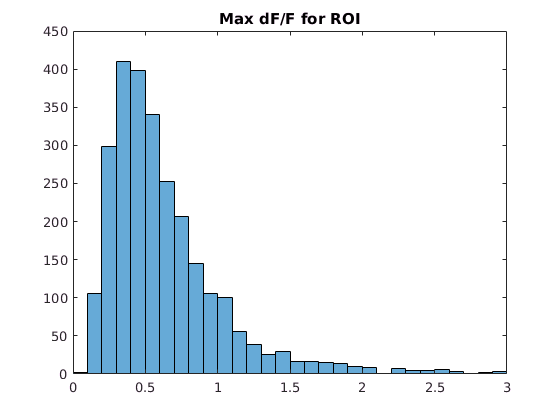


figure;
histogram(df_max);
title('Max dF/F for ROI')

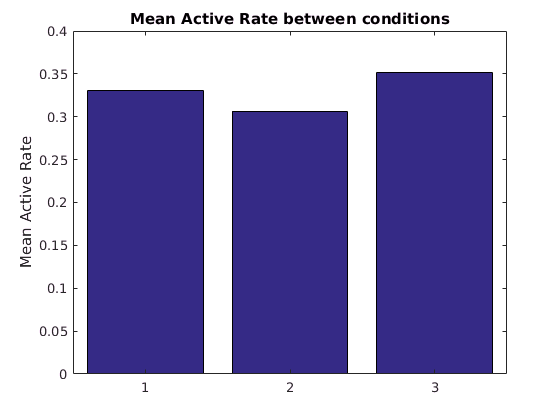

figure;
active_rate_means = arrayfun(@(x) mean(x.active_rate), F_stats);

wt_rates = active_rate_means(strcmpi(conditions,'mecp2wt'));
het_rates = active_rate_means(strcmpi(conditions,'mecp2het'));
ko_rates = active_rate_means(strcmpi(conditions,'mecp2ko'));

bar([mean(wt_rates); mean(het_rates); mean(ko_rates)]);
ylabel('Mean Active Rate');
title('Mean Active Rate between conditions');

sprintf('WT: mean %.2f std: %.2f', mean(wt_rates), std(wt_rates))

ans = WT: mean 0.33 std: 0.03

sprintf('Het: mean %.2f std: %.2f', mean(het_rates), std(het_rates))

ans = Het: mean 0.31 std: 0.04

sprintf('KO: mean %.2f std: %.2f', mean(ko_rates), std(ko_rates))

ans = KO: mean 0.35 std: 0.04

all_ipis = cell(nstats, 1);
for findex=1:nstats
    F_stat = F_stats(findex);
    peaks = F_stat.peaks;
    ncells = numel(peaks);
    ipis = cell(ncells,1);
    for i=1:ncells
        end_indecies = [peaks{i}.end_index];
        start_indecies = [peaks{i}.start_index];
        intervals = bsxfun(@minus,...
                           start_indecies(2:end),...
                           end_indecies(1:end-1));
        ipis{i} = intervals';
    end
    
    F_stat.ipi = ipis;
    all_ipis{findex} = ipis;
    
end

Best cluster count and clustering coefficient dist

max_clusters = 8;
cluster_coeffs = zeros(nstats,max_clusters);
mean_corr = zeros(nstats,1);
clusters_phase_shift = zeros(nstats,1);
for findex=1:nstats
    dF = F_stats(findex).dF;
    CORRS = corr(dF');
    mean_corr(findex) = mean(abs(CORRS(:)));
    for cluster_count = 2:max_clusters
        [cluster_index, ~, ~, ~] = kmeans(dF, cluster_count,...
            'Distance', 'correlation', 'Replicates', 5);
        cluster_coeffs(findex,cluster_count) = clusterCoeff(CORRS, cluster_index);
        if cluster_count == 2
            shifts = clusterMeanPhaseShift(dF, cluster_index);
            clusters_phase_shift(findex) = shifts(1,2);
        end
    end

end
[~, best_cluster_count] = max(cluster_coeffs,[],2);

% How good are the correlations
mean_correlation = mean(mean_corr)

mean_correlation = 0.3303

std_correlation = std(mean_corr)

std_correlation = 0.1461

Phase shifts between two clusters

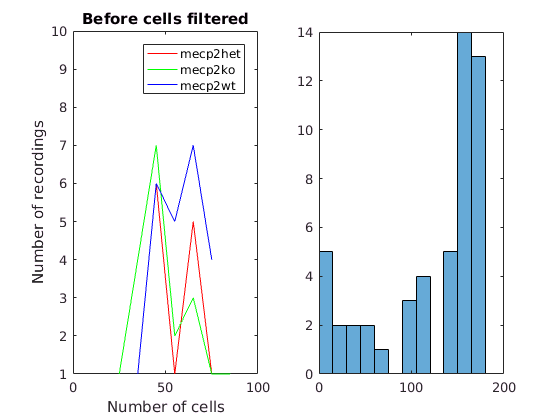

clusters_phase_shift = abs(clusters_phase_shift);
histogram(clusters_phase_shift, 'BinWidth', 15)

Two clusters best for % of recordings

sum(best_cluster_count == 2) / numel(best_cluster_count)

ans = 0.6275

Avg within clustering strength for cluster count

sum(cluster_coeffs) / nstats

ans =          0    0.3001    0.2088    0.1974    0.1714    0.1986    0.1832    0.1898


Plot peaks rise stats

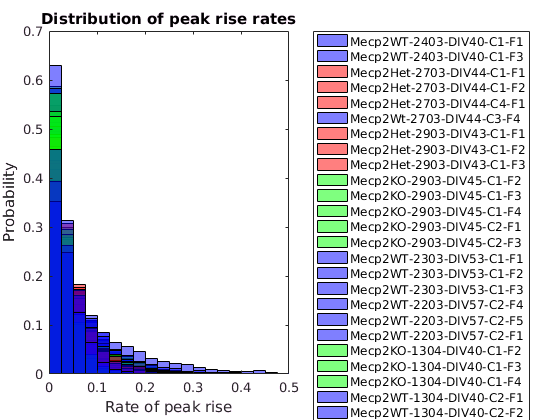

increase_rates = cell(numel(unique_conditions),1);
for i=1:numel(unique_conditions)
    increase_rates{i} = [];
end

fstats_legend = cell(nstats,1);
figure;
for findex=1:nstats
    F_stat = F_stats(findex);
    peaks = cell2mat(F_stat.peaks);
    fstats_legend{findex} = get_recording_name(F_stat.fileinfo);
    condtition = lower(F_stat.fileinfo.condition);
    c_index = condition_index(condtition);
    increase_rates{c_index} = [increase_rates{c_index} [peaks.increase_rate]];
    histogram([peaks.increase_rate], 'facealpha', 0.5,...
              'Normalization','probability',...
              'BinWidth', 0.025,...
              'FaceColor',condtion_colours(condtition),...
              'BinLimits', [0 0.5]);
    hold on;
end
hold off;
title('Distribution of peak rise rates');
xlabel('Rate of peak rise')
ylabel('Probability')
legend(fstats_legend, 'location', 'eastoutside');

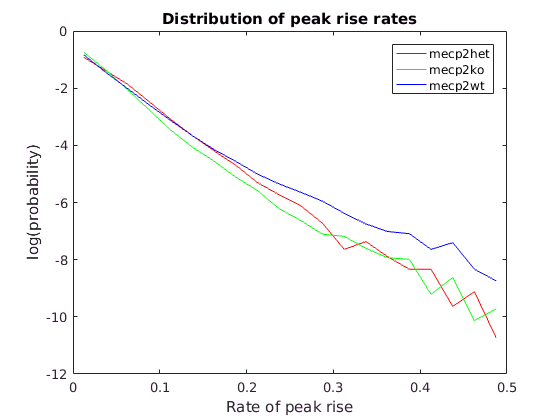

for i=1:numel(unique_conditions)
    colors = condtion_colours.values;
    bin_width = 0.025;
    [N,edges] = histcounts(increase_rates{i},....
          'Normalization','probability',...
          'BinWidth', bin_width,...
          'BinLimits', [0 0.5]);
    bin_centres = edges(1:end-1) + bin_width / 2;
    plot(bin_centres, log(N), 'Color', colors{i});
    hold on;
end
hold off;
title('Distribution of peak rise rates');
xlabel('Rate of peak rise')
xlim([0 0.5])
ylabel('log(probability)')
legend(unique_conditions);

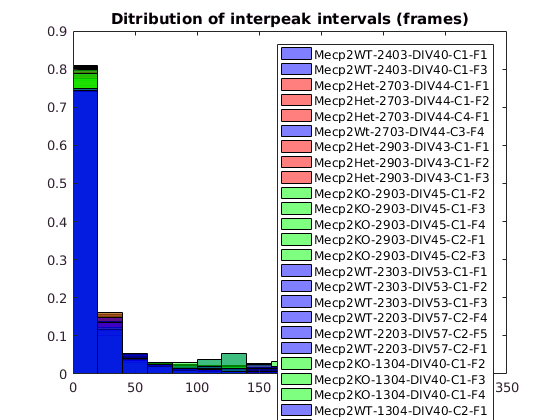

condition_ipis = cell(numel(unique_conditions),1);
for i=1:numel(unique_conditions)
    condition_ipis{i} = [];
end

fstats_legend = cell(nstats,1);
figure;
for findex=1:nstats
    F_stat = F_stats(findex);
    ipis = cell2mat(all_ipis{findex});
    condition = lower(F_stat.fileinfo.condition);
    c_index = condition_index(condition);
    condition_ipis{c_index} = [condition_ipis{c_index} ipis'];
    histogram(ipis, 'facealpha', 0.5,...
        'Normalization','probability',...
        'BinWidth', 20,...
        'FaceColor', condtion_colours(condition));
    fstats_legend{findex} = get_recording_name(F_stat.fileinfo);
    hold on;
end
hold off;
title('Ditribution of interpeak intervals (frames)');
legend(fstats_legend);

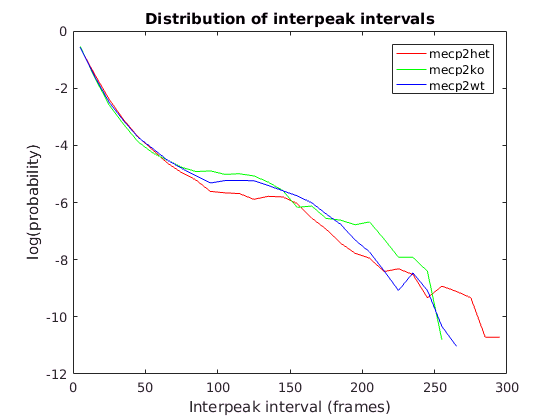


for i=1:numel(unique_conditions)
    colors = condtion_colours.values;
    bin_width = 10;
    [N,edges] = histcounts(condition_ipis{i},...
              'Normalization','probability',...
              'BinWidth', bin_width,...
              'BinLimits', [0 300]);
    bin_centres = edges(1:end-1) + bin_width / 2;
    plot(bin_centres, log(N), 'Color', colors{i});
    hold on;
end
hold off;
title('Distribution of interpeak intervals');
xlabel('Interpeak interval (frames)')
ylabel('log(probability)')
legend(unique_conditions);

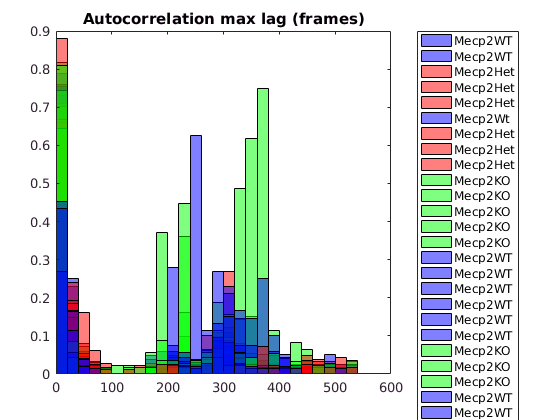

condition_acorrs = cell(numel(unique_conditions),1);
condition_lag_means = zeros(numel(F_stats),1);
for i=1:numel(unique_conditions)
    condition_acorrs{i} = [];
end

fstats_legend = cell(nstats,1);
figure;
for findex=1:nstats
    F_stat = F_stats(findex);
    c_index = condition_index(lower(F_stat.fileinfo.condition));
    condition_acorrs{c_index} = [condition_acorrs{c_index} F_stat.max_lag];
    
    condition_lag_means(findex) = mean(F_stat.max_lag(F_stat.max_lag > 100));
    histogram(F_stat.max_lag,'facealpha', 0.5,...
        'Normalization','probability',...
        'BinWidth',20,...
        'FaceColor', condtion_colours(lower(F_stat.fileinfo.condition)),...
        'DisplayName',F_stat.fileinfo.condition);
    hold on;
    finfo = F_stat.fileinfo;
    fstats_legend{findex} = get_recording_name(F_stat.fileinfo);
end
hold off;
title('Autocorrelation max lag (frames)');
legend('show', 'location', 'eastoutside');

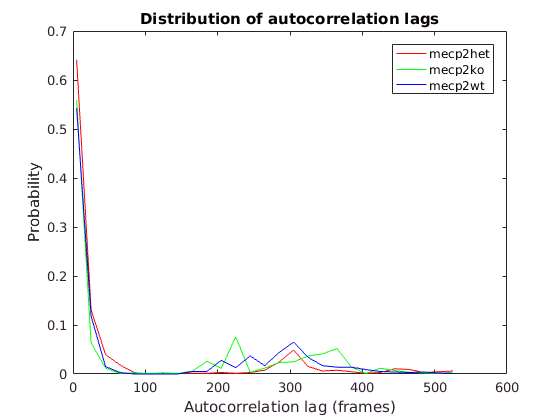

for i=1:numel(unique_conditions)
    colors = condtion_colours.values;
    [N,edges] = histcounts(condition_acorrs{i},...
              'Normalization','probability',...
              'BinWidth', 20);
    bin_centres = edges(1:end-1) + bin_width / 2;
    plot(bin_centres, N, 'Color', colors{i});
    hold on;
end
hold off;
title('Distribution of autocorrelation lags');
xlabel('Autocorrelation lag (frames)')
ylabel('Probability')
legend(unique_conditions);

p = 0.0126

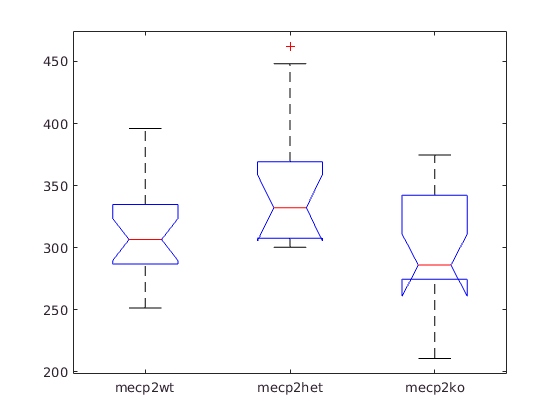

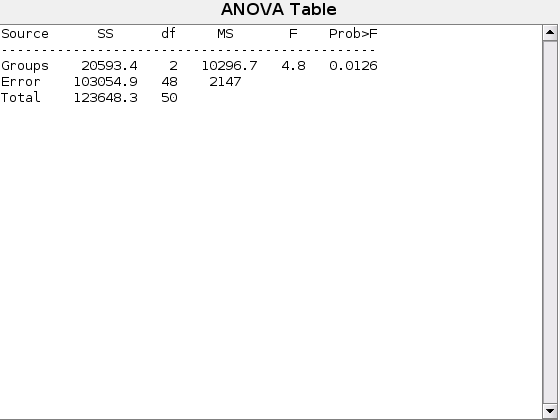

p=anova1(condition_lag_means, lower(conditions))

Anovas by other groupings

for findex=1:nstats
    F_stat = F_stats(findex);
    acorr = mean(F_stat.acorrs,1);
    max_lag = floor(length(acorr)/2);
    plot(-max_lag:max_lag, acorr,...
        'color', condtion_colours(lower(F_stat.fileinfo.condition)));
    hold on;
end
hold off;
title('Avg autocorrelation');
legend(fstats_legend, 'location', 'eastoutside');

Power at different frequencies

figure;
samplingRateHz = 2.8;
highestPowerFreq = zeros(nstats, 1);
sumPowerFreq = zeros(nstats, 1);

% for findex=1:nstats
%     dF =  F_stats(findex).dF;
%     denom = 0;
%     weightedFreq = 0;
%     for cell_index = 1:size(dF, 1)
%         [pxx, freqs] = pwelch(dF(cell_index,:),...
%                               500, 250, ...
%                               linspace(0.005, 0.025, 50),...
%                               samplingRateHz);
%         [maxP, I] = max(pxx);
%         weightedFreq = weightedFreq + freqs(I) * maxP;
%         denom = denom + maxP;
%         condition = lower(F_stats(findex).fileinfo.condition);
%         scatter(freqs(I),10*log10(maxP),...
%              [], condtion_colours(condition))
%         hold on;
%     end
%     highestPowerFreq(findex) = weightedFreq / denom; 
%     sumPowerFreq(findex) = sumPowerFreq(findex) + denom; 
% end
% hold off;
% xlabel('Frequency (Hz)');
% ylabel('Power (dB)');
% title('Maximum power spectra density for ROI')
% legend(unique_conditions)

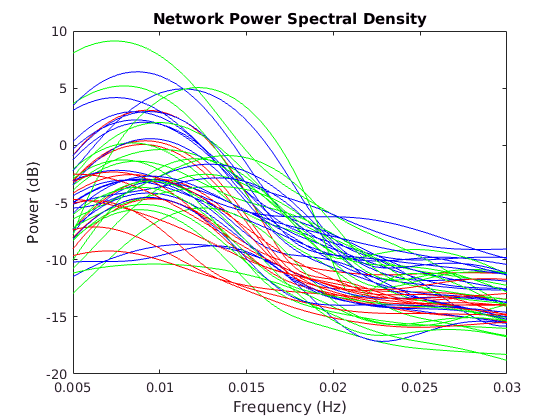

nfreqs = 60;
freqs = linspace(0.005, 0.03, nfreqs);
for findex = 1:numel(F_stats)
    
    F_stat = F_stats(findex);
    dF = F_stat.dF;
    ncells = size(dF, 1);
    pxx = zeros(ncells, nfreqs);
    for cell_index = 1:ncells
        [pxx_i, ~] = pwelch(dF(cell_index,:),...
            500, 250, ...
            linspace(0.005, 0.03, nfreqs), samplingRateHz);
        pxx(cell_index,:) = pxx_i;
    end
    
    networkPxx = sum(pxx / size(dF,1));
    condition = lower(F_stats(findex).fileinfo.condition);
    plot(freqs, 10 * log10(networkPxx), 'color', condtion_colours(condition));
    hold on;
    [maxPow, I] = max(networkPxx);
    highestPowerFreq(findex) = freqs(I);
    sumPowerFreq(findex) = maxPow;
end
hold off;
title('Network Power Spectral Density')
xlabel('Frequency (Hz)');
ylabel('Power (dB)');

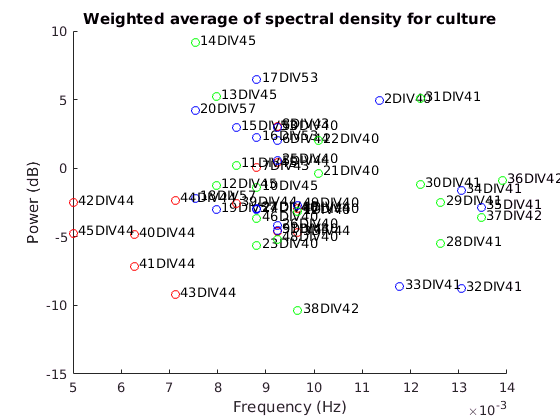

for findex=1:nstats    
    F_stat = F_stats(findex);
    condition = lower(F_stat.fileinfo.condition);
    x = highestPowerFreq(findex);
    y = 10*log10(sumPowerFreq(findex));
    scatter(x, y,...
            [], condtion_colours(condition))
    text(x + 0.0001, y + 0.2,...
        [num2str(findex) num2str(F_stat.fileinfo.div)])
    hold on;
end
hold off;
title('Weighted average of spectral density for culture')
xlabel('Frequency (Hz)');
ylabel('Power (dB)');

%legend(unique_conditions)

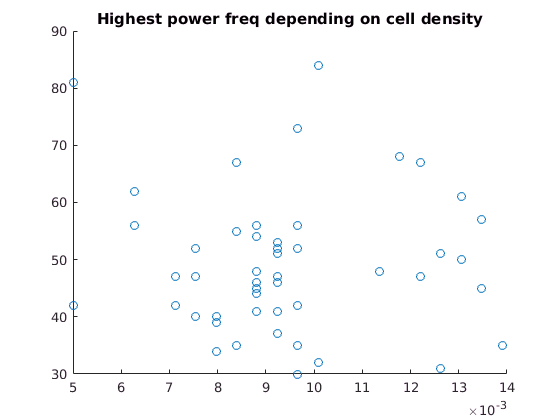

scatter(highestPowerFreq, [F_stats.ncells]');
title('Highest power freq depending on cell density')

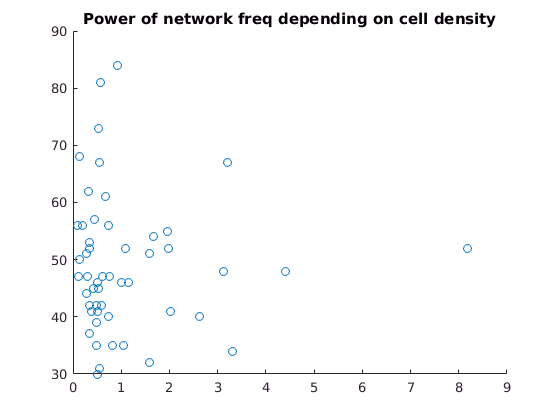

scatter(sumPowerFreq, [F_stats.ncells]');
title('Power of network freq depending on cell density')

F metrics

metrics = [];
for findex=1:nstats
    F_stat = F_stats(findex);
    dat = struct();
    dat.div = str2double(F_stat.fileinfo.div(4:end));
    dat.culture_date = F_stat.fileinfo.culture_date;
    dat.embryo_id = F_stat.fileinfo.embryo_id;
    dat.coverslip_id = F_stat.fileinfo.coverslip_id;
    dat.condition = lower(F_stat.fileinfo.condition);
    
    dat.ncells = size(F_stat.dF,1);
    dat.pcluster = best_cluster_count(findex);
    dat.cluster_coeff_best = cluster_coeffs(findex, best_cluster_count(findex));
    dat.cluster_coeff_two = cluster_coeffs(findex, 2);
    dat.cluster_phase_shift = clusters_phase_shift(findex);
    dat.highest_power_freq = highestPowerFreq(findex);
    dat.highest_oscillation_power = 10*log10(sumPowerFreq(findex));
    activity_rates = sum(F_stat.peak_extends, 2)' / size(all_F_stats(i).dF, 2);
    dat.activity_rate_mean = mean(activity_rates);
    dat.activity_rate_std = std(activity_rates);
    events_count = cellfun(@(x) numel(x), F_stat.peaks');
    dat.events_count_mean = mean(events_count);
    dat.events_count_std = std(events_count);
    
    peaks_mat = cell2mat(F_stat.peaks);
    dat.event_ampl_mean = mean([peaks_mat.amplitude]);
    dat.event_ampl_std = std([peaks_mat.amplitude]);
    dat.event_ampl_std = std([peaks_mat.amplitude]);
    ipis_cell = all_ipis(findex);
    ipis = cell2mat(ipis_cell{1});
    dat.ipis_mean = mean(ipis);
    dat.ipis_std = std(ipis);
    
    metrics = [metrics dat];
end
mtable=struct2table(metrics);
writetable(mtable, 'metrics.csv')

function name = get_recording_name(finfo)
    name = [finfo.condition '-'...
            finfo.culture_date '-'...
            finfo.div '-'...
            'C' finfo.coverslip_id '-'...
            'F' finfo.fr_id...
           ];
end